Question 1

%fsolve

x = [1, 4, 2, 3, 1, 0, 0, 2];
x1 = [1, 2, 3, 4, 5, 6];

d=dbfeq(x1);

f=dbfilter(1);


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the selected value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>




f2=dbfilter(2);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the selected value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>





f3=dbfilter(3);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the selected value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>





f=f*sqrt(2)

f =     0.7071    0.7071


f2=f2*sqrt(2)

f2 =    -0.0915    0.1585    0.5915    0.3415


f3=f3*sqrt(2)

f3 =     0.3327    0.8069    0.4599   -0.1350   -0.0854    0.0352



%Haar wavelets coefficients 

H0db2=[1 1]/sqrt(2)

H0db2 =     0.7071    0.7071


H0db4=[(1+sqrt(3)) (3+sqrt(3)) (3-sqrt(3)) (1-sqrt(3))]/(4*sqrt(2)) % Haar low-pass

H0db4 =     0.4830    0.8365    0.2241   -0.1294


H1db4=fliplr(H0db4).*[1 -1 1 -1] % DB4 high-pass (alternating flip)

H1db4 =    -0.1294   -0.2241    0.8365   -0.4830



H0db6=(sqrt(2)/32)*[1+sqrt(10)+sqrt(5+2*sqrt(10)) 5+sqrt(10)+3*sqrt(5+2*sqrt(10)) 10-2*sqrt(10)+2*sqrt(5+2*sqrt(10)) 10-2*sqrt(10)-2*sqrt(5+2*sqrt(10)) 5+sqrt(10)-3*sqrt(5+2*sqrt(10)) 1+sqrt(10)-sqrt(5+2*sqrt(10))] % DB6 low-pass

H0db6 =     0.3327    0.8069    0.4599   -0.1350   -0.0854    0.0352


Question 2

clear

load('dataset1.mat');
%s1=s;
%figure
%plot(s1)
%fl=dbfilter(1)
%*sqrt(2);
%fh=fliplr(fl).*[1 -1];

fl=dbfilter(3)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the selected value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



fl =     0.2352    0.5706    0.3252   -0.0955   -0.0604    0.0249


fh=fliplr(fl).*[1 -1 1 -1 1 -1] % DB4 high-pass (alternating flip)

fh =     0.0249    0.0604   -0.0955   -0.3252    0.5706   -0.2352


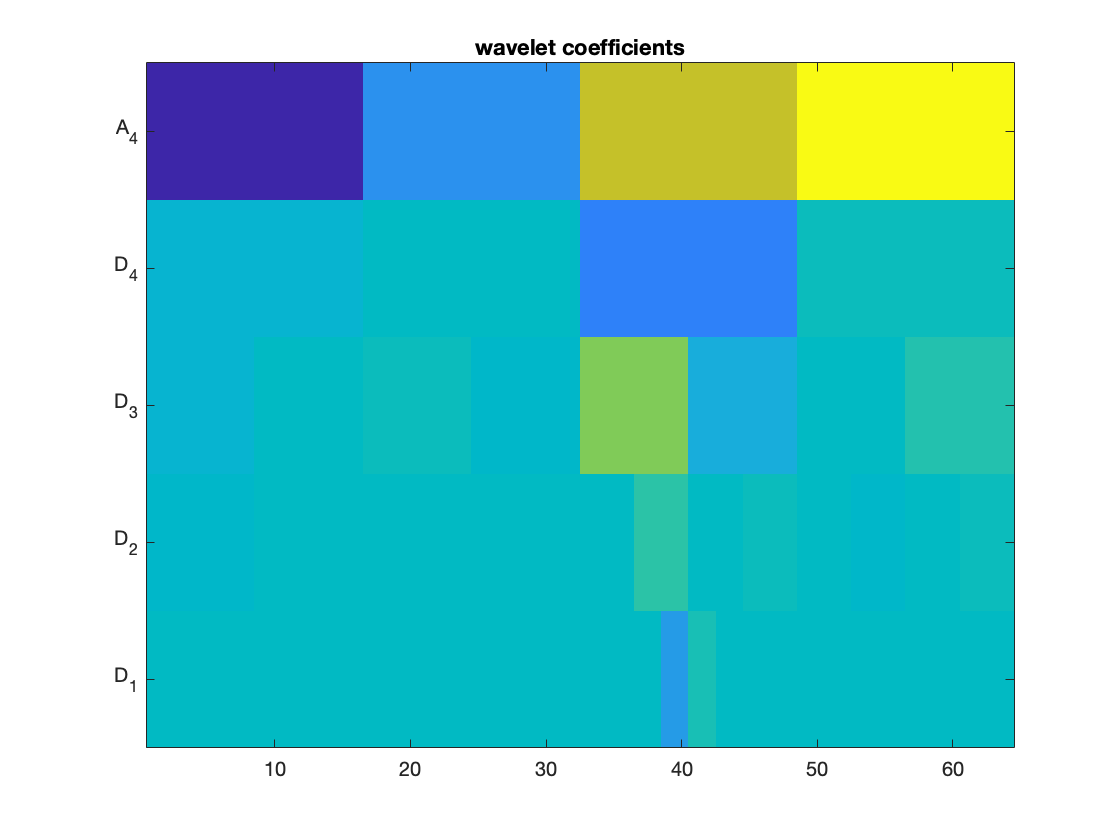

%fl=dbfilter(4)
%fl=dbwavf('db4')
%fh=fliplr(fl).*[1 -1 1 -1 1 -1 1 -1] % DB4 high-pass (alternating flip)
%db4=[0.1629    0.5055    0.4461   -0.0198   -0.1323    0.0218    0.0233   -0.0075]
%fh=fliplr(fl).*[1 -1 1 -1 1 -1 1 -1]

%s1 = [1, 2,5,7,-2,9,4,20,3,4,5,2,3,1,0,3];
%s1= 1:64;
%s1=s1'
[a1,b1]=discreteWaveletTransform(s,fl,fh);
[a2,b2]=dwt(s,'db4');

%[c,l] = dwt(s,'db1')
%Xm = idwt(a2,b2,'db1');
X = idwt(a2,b2,'db4');
X2 = invDaubechies1D(a1,b1,fl,fh);
%built in function matlab toolbox
%[c,d]=dwt(s1,'db1')
%single step in the Daubechies 2 wavelet transform

[C]=multiresolutionAnalysis(s,4,fl,fh);

%output should be
%C = [app:coef:(J 􀀀 j)jdet:coef:(J 􀀀 j)j : : : jdet:coef:(J)]
%[c3,d3]=wavedec(s1,4,'db1')
figure;
plotWaveletDecompositionMap(C,4,length(s));


load('dataset2.mat');
s2=s;
[a2,b2]=discreteWaveletTransform(s2,fl,fh);
C2=multiresolutionAnalysis(s2,4,fl,fh);

figure;
%plotWaveletDecompositionMap(C2,4,length(s2),1);
